# Pattern Classification - [tutorial](https://nl.mathworks.com/videos/image-recognition-using-machine-learning-122900.html)

## Data description

Our dataset consists of 4 objects: anchor, butterfly, cup and flamingo.

### Read images

imds = imageDatastore('images\task_1', "IncludeSubfolders",true,"LabelSource","foldernames");

### Display class names and counts

tbl = countEachLabel(imds);
categories = tbl.Label;

### Display sampling of image data

Here we select some 9 images from one of the image sets.

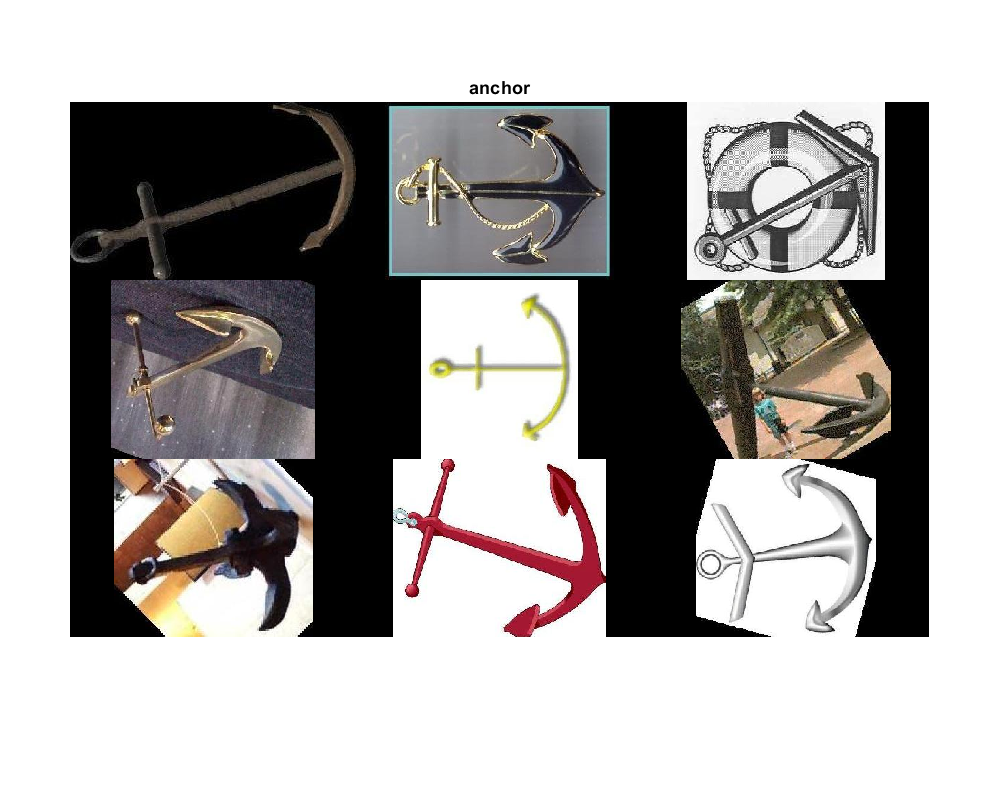

sample = splitEachLabel(imds,9);

montage(sample.Files(1:9));
title(char(tbl.Label(1)));

### Show sampling of all data

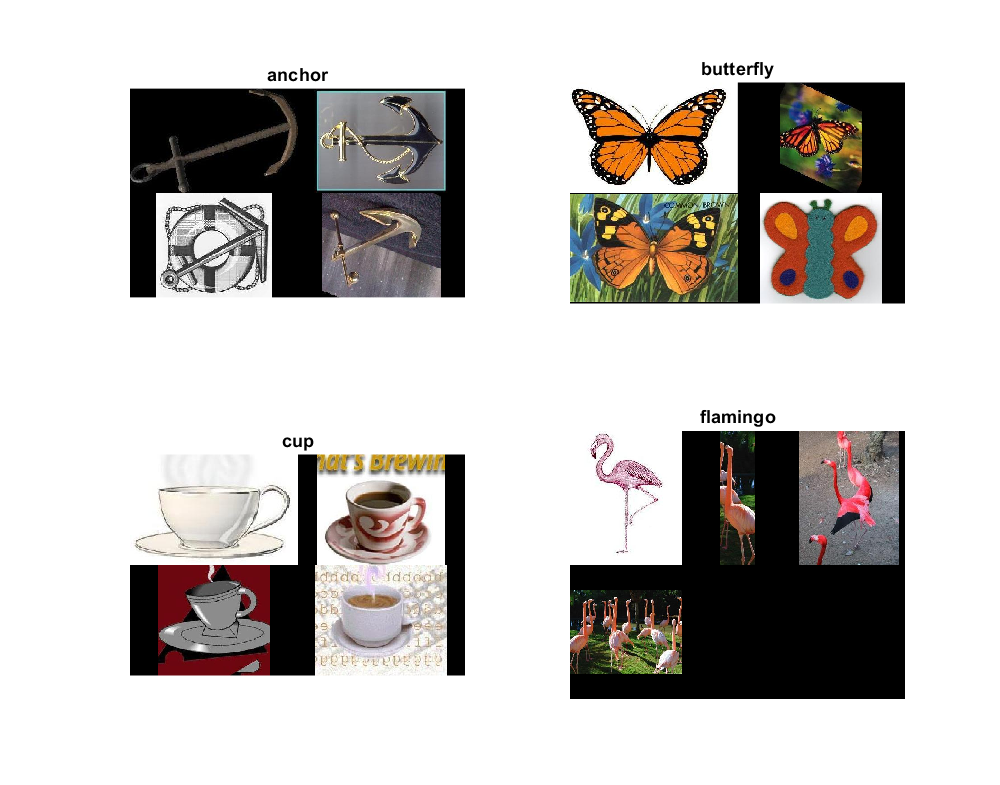

for ii = 1:4
    sf = (ii-1)*9 +1;
    ax(ii) = subplot(2,2,ii);
    montage(sample.Files(sf:sf+3));
    title(char(tbl.Label(ii)));
end

## Pre-processing stage of the training data

### Feature extraction using "Bag of Features"

Bag of Features, also defined as Bag of Visual Words, is a way to extract features from images. In order to represent an image with this approach, an image can be treated as a document and occurance of visual "words" in images are used to generate a histogram that represents an image.

Basically, we count the number of times that we see some words, and based on their frequency we can describe those objects or scenes.

### Partition 30 images for training and 10 for testing

We do this partition by using a separate script.

[training_set, test_set] = prepareInputFiles(imds)

training_set =   1×4 imageSet array with properties:

    Description
    ImageLocation
    Count


test_set =   1×4 imageSet array with properties:

    Description
    ImageLocation
    Count


### Create Visual Vocabulary

tic
% Define the words
bag = bagOfFeatures(training_set,'VocabularySize',250,'PointSelection','Detector');

Creating Bag-Of-Features.
-------------------------
* Image category 1: anchor
* Image category 2: butterfly
* Image category 3: cup
* Image category 4: flamingo
* Selecting feature point locations using the Detector method.
* Extracting SURF features from the selected feature point locations.
** detectSURFFeatures is used to detect key points for feature extraction.

* Extracting features from 30 images in image set 1...done. Extracted 7590 features.
* Extracting features from 30 images in image set 2...done. Extracted 6759 features.
* Extracting features from 30 images in image set 3...done. Extracted 4250 features.
* Extracting features from 30 images in image set 4...done. Extracted 5459 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 3 has the least number of strongest features: 3400.
** Using the stro

% Count the occurences
scenedata = double(encode(bag, training_set));

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: anchor
* Image category 2: butterfly
* Image category 3: cup
* Image category 4: flamingo
* Encoding 30 images from image set 1...done.
* Encoding 30 images from image set 2...done.
* Encoding 30 images from image set 3...done.
* Encoding 30 images from image set 4...done.

* Finished encoding images.



toc

Elapsed time is 9.747637 seconds.


%return;

### Visualize Feature vectors

img = read(training_set(1), randi(training_set(1).Count));
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


figure;
subplot(4,2,1); imshow(img);
subplot(4,2,2); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

img = read(training_set(2), randi(training_set(2).Count));
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


subplot(4,2,3); imshow(img);
subplot(4,2,4);
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');
img = read(training_set(3), randi(training_set(3).Count));
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


subplot(4,2,5); imshow(img);
subplot(4,2,6); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

img = read(training_set(4), randi(training_set(4).Count));
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


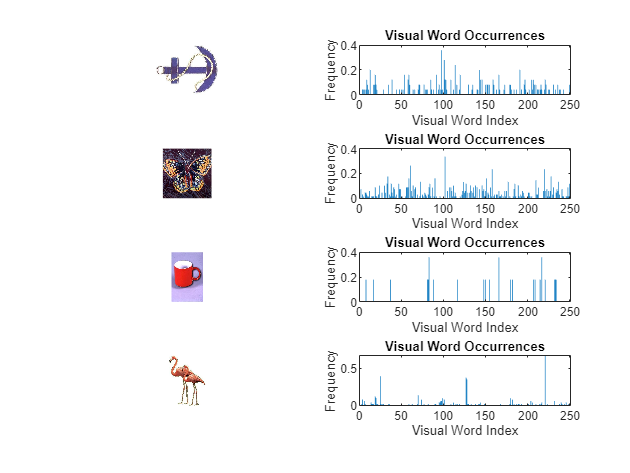

subplot(4,2,7); imshow(img);
subplot(4,2,8); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

### Create table using the encoded features

Here we create a table that we are going to use for the classification learner in order to get the necessary results.

SceneImageData = array2table(scenedata);
sceneType = categorical(repelem({training_set.Description}', [training_set.Count], 1));
SceneImageData.sceneType = sceneType;
correctTrainModel = trainClassifier(SceneImageData);

### Determine the accuracy on the test image set

testSceneData = double(encode(bag, test_set));

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: anchor
* Image category 2: butterfly
* Image category 3: cup
* Image category 4: flamingo
* Encoding 10 images from image set 1...done.
* Encoding 10 images from image set 2...done.
* Encoding 10 images from image set 3...done.
* Encoding 10 images from image set 4...done.

* Finished encoding images.



testSceneData = array2table(testSceneData,'VariableNames',correctTrainModel.RequiredVariables);
actualSceneType = categorical(repelem({test_set.Description}', [test_set.Count], 1));
predictedOutcome = correctTrainModel.predictFcn(testSceneData);
correctPredictions = (predictedOutcome == actualSceneType);
validationAccuracy = sum(correctPredictions)/length(predictedOutcome) %#ok

validationAccuracy = 0.1500

### Visualizing the classifier

ii = randi(size(test_set,2));
jj = randi(test_set(ii).Count);
img = read(test_set(ii),jj);

figure;
imshow(img);

We now invoke the trained classifier:

imagefeatures = double(encode(bag, img));

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


Then find two closest matches for each feature

[bestGuess, score] = predict(correctTrainModel.ClassificationSVM,imagefeatures);

Display the result as a label to the image.

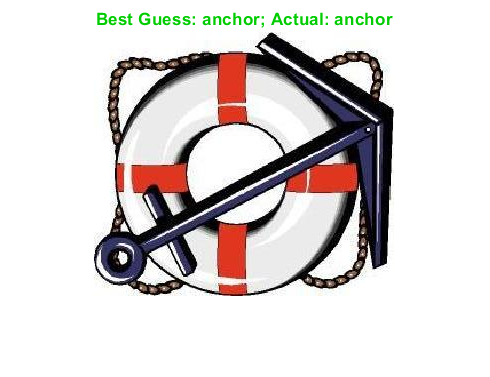

if strcmp(char(bestGuess),test_set(ii).Description)
	titleColor = [0 0.8 0];
else
	titleColor = 'r';
end
title(sprintf('Best Guess: %s; Actual: %s',...
	char(bestGuess),test_set(ii).Description),...
	'color',titleColor)